# Copyright of this code belongs to Dipankar Maity (dmaity@uncc.edu).

Do not distribute this code.

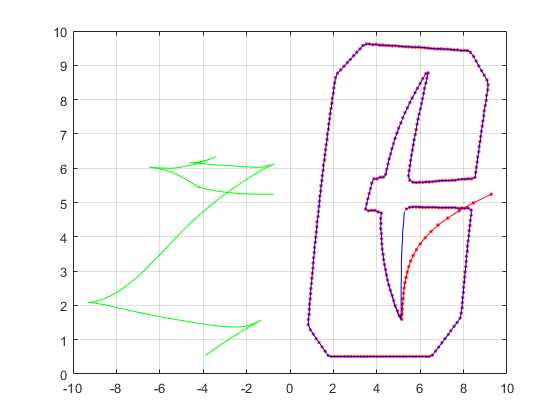

clear all 
% 'D' is the distance of the pen from the base of the robot
% 'k' is the control parameter
global D h k m;

down_sample_amount = 15;

% Circle

position = importdata("CharlotteLogo.mat");
D =10; k =10; h = .02;
position  = position'/100;

l = 1;
for i = 1:down_sample_amount:length(position)
    new_position(:,l) = position(:,i);
    l = l+1;
end
position = new_position;
     
      
state(:,1) =[position(1,1)-6; position(2,1)+.5; 0];
xb(1) = state(1,1) + D*cos(state(3,1));
yb(1) = state(2,1) + D*sin(state(3,1));
theta(1) = state(3,1); 
  
  T = size(position,2)-1;
  t = 1:T;
  xVelocity = (position(1,t+1) - position(1,t))/h;
  yVelocity = (position(2,t+1) - position(2,t))/h;
  
velocity_v= [xVelocity; yVelocity];
for i = 1:T-1
    velocity_w(i) =  atan2(xVelocity(i+1),yVelocity(i+1))-atan2(xVelocity(i),yVelocity(i));
end

for i= 1:T
reference_velocity(i) = norm(velocity_v(:,i));
end 

for t =1 : T
    n1 = 0*randn(1);
    n2 = 0*randn(1);
    % x= current state
    x= [xb(t); yb(t); theta(t)];
    
    % controller returns the desired velocities
    [v, w] = controller(x, xVelocity(t), yVelocity(t),position(:,t));
    
    % use the dynamics with desired velocities to generate the velocities
    dot_x = dynamics(x,v,w,n1,n2);
    
     linear_vel(t) = v+n1;
     angular_vel(t) = w+n2;
     
    % integrate the position to get the new position
    xb(t+1) = xb(t) + dot_x(1)*h;
    yb(t+1) = yb(t) + dot_x(2)*h;
    theta(t+1) = theta(t) + dot_x(3)*h;
    
    % centroid dynamics
    state(:,t+1) = state(:,t) + h* [(v+n1)*cos(state(3,t)); (v+n1)*sin(state(3,t)); w+n2];
    
end

figure
plot(xb, yb, '.-','color','r')
hold on;
plot(state(1,:), state(2,:), 'g'); 
plot(position(1,:),position(2,:),'color','b');
grid on;
% legend('Pen location', 'robot centroid', 'reference trajectory', "location", 'southeast')
hold off

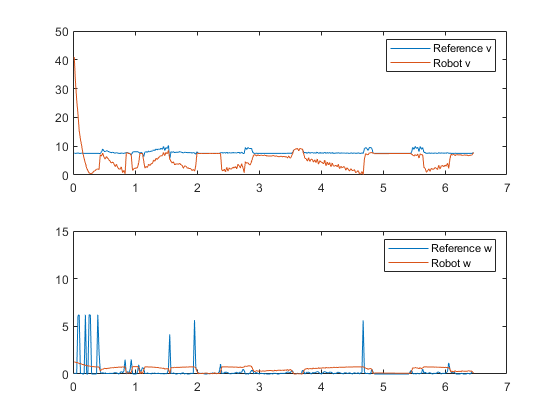


figure
subplot(2,1,1)
plot([1:size(linear_vel,2)]*h, reference_velocity);
hold on
plot([1:size(linear_vel,2)]*h, abs(linear_vel));
legend('Reference v', 'Robot v')
hold off
subplot(2,1,2)
plot([1:size(angular_vel,2)-1]*h, abs(velocity_w));
hold on
plot([1:size(angular_vel,2)]*h, abs(angular_vel));
legend('Reference w', 'Robot w')
hold off

subplot(2,1,1)
xlim([0 7])
ylim([0 50])
subplot(2,1,2)
xlim([0 7])
ylim([0 15])

function [v, w] = controller(x, xVelocity, yVelocity,position)
global D k m
 

J = [cos(x(3)) -D*sin(x(3));
    sin(x(3))  D*cos(x(3)) ];
E = x(1:2,1)- [position(1); position(2)];

% if norm(E) > m
%         v_feedback = [xVelocity; yVelocity] - k*m/norm(E)*E;
%     else
    v_feedback = [xVelocity; yVelocity] - k*E;
% end

desired_control = (J)\v_feedback;

v = desired_control(1);
w = desired_control(2);

end

function dot_x = dynamics(x,v,w,n1,n2)
global D

M = [cos(x(3)) -D*sin(x(3));
     sin(x(3))  D*cos(x(3));
     0          1          ];

dot_x = M*[v+n1; w+n2];

end